model='mdl';
load_mdl_data;
load_init_states;

## 按剖面计算

vRange = 30:50;
hRange = 0:1000:5000;

tic;
[op,opreport,params] = trim_lon_HV(model, vRange, hRange);
REPS = numel(op);
totalTime = toc;
averageTime = totalTime/REPS;
fprintf('averageTime=%f, totalTime=%f, loop=%d\n',averageTime, totalTime,REPS);

averageTime=1.194100, totalTime=150.456613, loop=126


## 绘制静平衡曲线

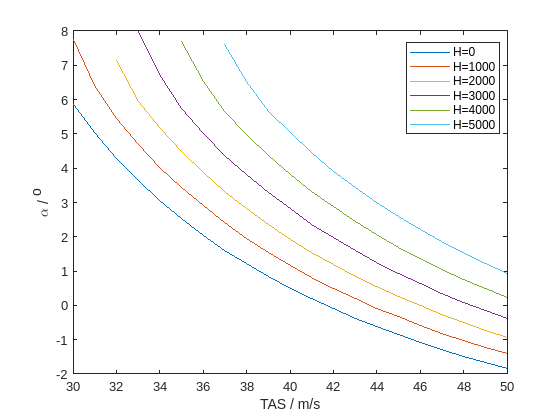

h1 = figure;
h2 = figure;
h3 = figure;
nV = length(vRange);
nH = length(hRange);
for h=1:nH
    aoa_trim = zeros(nV,1)*NaN;
    de_trim = zeros(nV,1)*NaN;
    thr_trim = zeros(nV,1)*NaN;
    EAS_trim = zeros(nV,1)*NaN;
    for v=1:nV
        if opreport(v,h).OptimizationOutput.constrviolation < 1e-6
          aoa_trim(v) = op(v,h).States(2).x * 57.29;
          de_trim(v) = op(v,h).Inputs(2).u * 57.29;
          thr_trim(v) = op(v,h).Inputs(4).u;
          EAS_trim(v) = opreport(v,h).Outputs(13).y;
        end
    end
    label = sprintf("H=%.0f", hRange(h));
    figure(h1);
    plot(vRange, aoa_trim,'DisplayName',label);
    hold on;
    figure(h2);
    plot(vRange, de_trim,'DisplayName',label);
    hold on;
    figure(h3);
    plot(vRange, thr_trim,'DisplayName',label);
    hold on;
end
figure(h1);
xlabel('TAS / m/s');
ylabel('\alpha / ^o');
legend('Location','best');

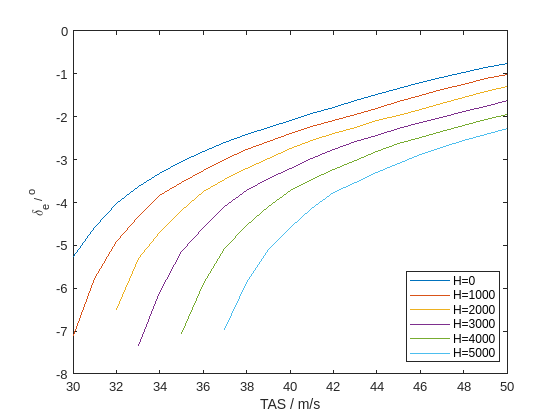

figure(h2);
xlabel('TAS / m/s');
ylabel('\delta_e / ^o');
legend('Location','best');

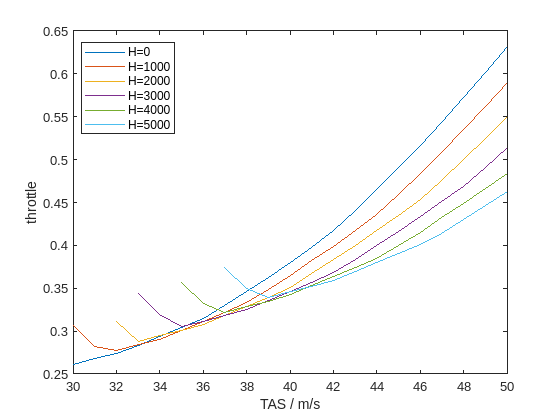

figure(h3);
xlabel('TAS / m/s');
ylabel('throttle');
legend('Location','best');

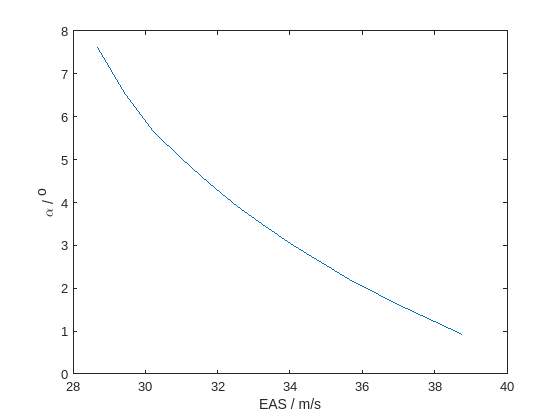


figure;
plot(EAS_trim, aoa_trim);
xlabel('EAS / m/s');
ylabel('\alpha / ^o');

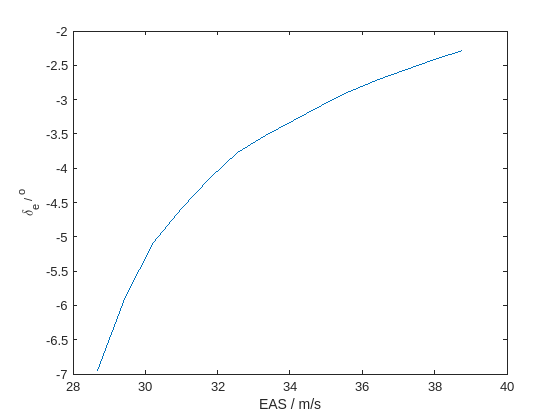


figure;
plot(EAS_trim, de_trim);
xlabel('EAS / m/s');
ylabel('\delta_e / ^o');

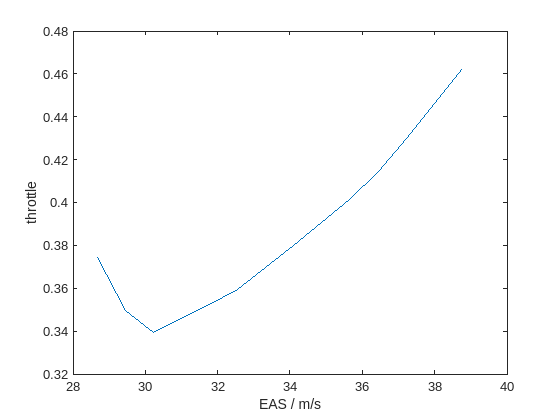


figure;
plot(EAS_trim, thr_trim);
xlabel('EAS / m/s');
ylabel('throttle');

#### 建立线性化模型

tic;
G = linearize(model,op,params);

[~,~,m,n]=size(G);
sysLon = cell(m,n);
sysLat = cell(m,n);
for idx_v=1:m
    for idx_h=1:n
        sys = G(:,:,idx_v,idx_h);
        name = sprintf("v=%.1f", vRange(idx_v));
        sysLon{idx_v, idx_h} = ss(sys.A([1 2 5 8],[1 2 5 8]),sys.B([1 2 5 8],[2 4]), eye(4), zeros(4,2), ...
            'StateName',{'V' 'alpha','q','theta'},...
            'InputName',{'de','throttle'},...
            'OutputName',{'V' 'alpha','q','theta'},...
            'Name', name);
        sysLat{idx_v, idx_h} = ss(sys.A([3 4 6 7],[3 4 6 7]),sys.B([3 4 6 7],[1 3]), eye(4), zeros(4,2), ...
            'StateName',{'beta' 'p','r','phi'},...
            'InputName',{'da','dr'},...
            'OutputName',{'beta' 'p','r','phi'},...
            'Name', name);
    end
end

REPS = m*n;
totalTime = toc;
averageTime = totalTime/REPS;
fprintf('averageTime=%f, totalTime=%f, loop=%d\n',averageTime, totalTime,REPS);

averageTime=0.214948, totalTime=27.083448, loop=126


#### 纵向模态分析

idx_h = 1;
figure;
for idx_v=1:m
    pzplot(sysLon{idx_v, idx_h});
    hold on;
    disp(sysLon{idx_v, idx_h}.Name)
    damp(sysLon{idx_v, idx_h})
    disp(' ')
end

v=30.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.71e-03 + 4.32e-01i     2.25e-02       4.32e-01         1.03e+02    
 -9.71e-03 - 4.32e-01i     2.25e-02       4.32e-01         1.03e+02    
 -1.28e+00 + 2.79e+00i     4.16e-01       3.07e+00         7.81e-01    
 -1.28e+00 - 2.79e+00i     4.16e-01       3.07e+00         7.81e-01    


v=31.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.60e-03 + 4.18e-01i     2.30e-02       4.18e-01         1.04e+02    
 -9.60e-03 - 4.18e-01i     2.30e-02       4.18e-01         1.04e+02    
 -1.32e+00 + 2.83e+00i     4.22e-01       3.12e+00         7.59e-01    
 -1.32e+00 - 2.83e+00i     4.22e-01       3.12e+00         7.59e-01    


v=32.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.44e-03 + 4.05e-01i     2.33e-02       4.05e-01         1.06e+02    
 -9.44e-03 - 4.05e-01i     2.33e-02       4.05e-01         1.06e+02    
 -1.35e+00 + 2.87e+00i     4.27e-01       3.17e+00         7.39e-01    
 -1.35e+00 - 2.87e+00i     4.27e-01       3.17e+00         7.39e-01    


v=33.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -7.50e-03 + 3.79e-01i     1.98e-02       3.79e-01         1.33e+02    
 -7.50e-03 - 3.79e-01i     1.98e-02       3.79e-01         1.33e+02    
 -1.42e+00 + 2.51e+00i     4.93e-01       2.88e+00         7.03e-01    
 -1.42e+00 - 2.51e+00i     4.93e-01       2.88e+00         7.03e-01    


v=34.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.22e-03 + 3.68e-01i     2.23e-02       3.68e-01         1.22e+02    
 -8.22e-03 - 3.68e-01i     2.23e-02       3.68e-01         1.22e+02    
 -1.46e+00 + 2.58e+00i     4.93e-01       2.97e+00         6.83e-01    
 -1.46e+00 - 2.58e+00i     4.93e-01       2.97e+00         6.83e-01    


v=35.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.84e-03 + 3.58e-01i     2.47e-02       3.58e-01         1.13e+02    
 -8.84e-03 - 3.58e-01i     2.47e-02       3.58e-01         1.13e+02    
 -1.51e+00 + 2.66e+00i     4.93e-01       3.06e+00         6.64e-01    
 -1.51e+00 - 2.66e+00i     4.93e-01       3.06e+00         6.64e-01    


v=36.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -9.38e-03 + 3.49e-01i     2.69e-02       3.49e-01         1.07e+02    
 -9.38e-03 - 3.49e-01i     2.69e-02       3.49e-01         1.07e+02    
 -1.55e+00 + 2.74e+00i     4.92e-01       3.14e+00         6.46e-01    
 -1.55e+00 - 2.74e+00i     4.92e-01       3.14e+00         6.46e-01    


v=37.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.01e-02 + 3.33e-01i     3.04e-02       3.33e-01         9.85e+01    
 -1.01e-02 - 3.33e-01i     3.04e-02       3.33e-01         9.85e+01    
 -1.61e+00 + 2.64e+00i     5.21e-01       3.10e+00         6.20e-01    
 -1.61e+00 - 2.64e+00i     5.21e-01       3.10e+00         6.20e-01    


v=38.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.09e-02 + 3.25e-01i     3.35e-02       3.25e-01         9.19e+01    
 -1.09e-02 - 3.25e-01i     3.35e-02       3.25e-01         9.19e+01    
 -1.65e+00 + 2.72e+00i     5.20e-01       3.18e+00         6.04e-01    
 -1.65e+00 - 2.72e+00i     5.20e-01       3.18e+00         6.04e-01    


v=39.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.15e-02 + 3.17e-01i     3.64e-02       3.17e-01         8.67e+01    
 -1.15e-02 - 3.17e-01i     3.64e-02       3.17e-01         8.67e+01    
 -1.70e+00 + 2.79e+00i     5.20e-01       3.26e+00         5.89e-01    
 -1.70e+00 - 2.79e+00i     5.20e-01       3.26e+00         5.89e-01    


v=40.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.21e-02 + 3.09e-01i     3.93e-02       3.09e-01         8.23e+01    
 -1.21e-02 - 3.09e-01i     3.93e-02       3.09e-01         8.23e+01    
 -1.74e+00 + 2.86e+00i     5.20e-01       3.35e+00         5.75e-01    
 -1.74e+00 - 2.86e+00i     5.20e-01       3.35e+00         5.75e-01    


v=41.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.27e-02 + 3.01e-01i     4.21e-02       3.02e-01         7.87e+01    
 -1.27e-02 - 3.01e-01i     4.21e-02       3.02e-01         7.87e+01    
 -1.78e+00 + 2.93e+00i     5.20e-01       3.43e+00         5.61e-01    
 -1.78e+00 - 2.93e+00i     5.20e-01       3.43e+00         5.61e-01    


v=42.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.48e-02 + 3.02e-01i     4.89e-02       3.02e-01         6.77e+01    
 -1.48e-02 - 3.02e-01i     4.89e-02       3.02e-01         6.77e+01    
 -1.85e+00 + 3.39e+00i     4.78e-01       3.86e+00         5.42e-01    
 -1.85e+00 - 3.39e+00i     4.78e-01       3.86e+00         5.42e-01    


v=43.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.54e-02 + 2.95e-01i     5.22e-02       2.96e-01         6.49e+01    
 -1.54e-02 - 2.95e-01i     5.22e-02       2.96e-01         6.49e+01    
 -1.89e+00 + 3.48e+00i     4.78e-01       3.96e+00         5.29e-01    
 -1.89e+00 - 3.48e+00i     4.78e-01       3.96e+00         5.29e-01    


v=44.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.60e-02 + 2.89e-01i     5.55e-02       2.89e-01         6.24e+01    
 -1.60e-02 - 2.89e-01i     5.55e-02       2.89e-01         6.24e+01    
 -1.93e+00 + 3.56e+00i     4.77e-01       4.05e+00         5.17e-01    
 -1.93e+00 - 3.56e+00i     4.77e-01       4.05e+00         5.17e-01    


v=45.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.66e-02 + 2.82e-01i     5.87e-02       2.83e-01         6.02e+01    
 -1.66e-02 - 2.82e-01i     5.87e-02       2.83e-01         6.02e+01    
 -1.98e+00 + 3.64e+00i     4.77e-01       4.15e+00         5.06e-01    
 -1.98e+00 - 3.64e+00i     4.77e-01       4.15e+00         5.06e-01    


v=46.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.71e-02 + 2.76e-01i     6.20e-02       2.77e-01         5.83e+01    
 -1.71e-02 - 2.76e-01i     6.20e-02       2.77e-01         5.83e+01    
 -2.02e+00 + 3.73e+00i     4.77e-01       4.24e+00         4.95e-01    
 -2.02e+00 - 3.73e+00i     4.77e-01       4.24e+00         4.95e-01    


v=47.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.77e-02 + 2.70e-01i     6.52e-02       2.71e-01         5.66e+01    
 -1.77e-02 - 2.70e-01i     6.52e-02       2.71e-01         5.66e+01    
 -2.06e+00 + 3.81e+00i     4.76e-01       4.33e+00         4.84e-01    
 -2.06e+00 - 3.81e+00i     4.76e-01       4.33e+00         4.84e-01    


v=48.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.82e-02 + 2.65e-01i     6.85e-02       2.65e-01         5.50e+01    
 -1.82e-02 - 2.65e-01i     6.85e-02       2.65e-01         5.50e+01    
 -2.11e+00 + 3.89e+00i     4.76e-01       4.43e+00         4.74e-01    
 -2.11e+00 - 3.89e+00i     4.76e-01       4.43e+00         4.74e-01    


v=49.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.87e-02 + 2.59e-01i     7.18e-02       2.60e-01         5.36e+01    
 -1.87e-02 - 2.59e-01i     7.18e-02       2.60e-01         5.36e+01    
 -2.15e+00 + 3.98e+00i     4.76e-01       4.52e+00         4.65e-01    
 -2.15e+00 - 3.98e+00i     4.76e-01       4.52e+00         4.65e-01    


v=50.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.91e-02 + 2.54e-01i     7.50e-02       2.55e-01         5.23e+01    
 -1.91e-02 - 2.54e-01i     7.50e-02       2.55e-01         5.23e+01    
 -2.19e+00 + 4.06e+00i     4.75e-01       4.62e+00         4.56e-01    
 -2.19e+00 - 4.06e+00i     4.75e-01       4.62e+00         4.56e-01    


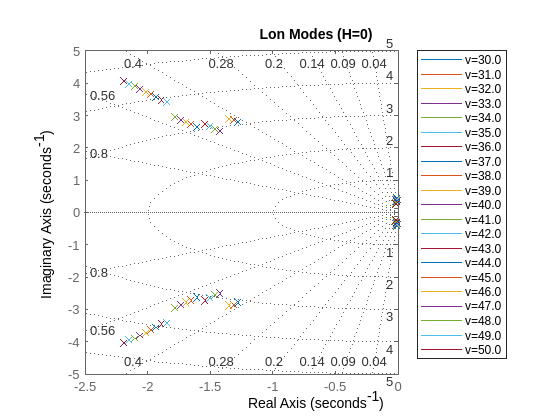

label = sprintf('Lon Modes (H=%.0f)',hRange(idx_h));
title(label);
grid on;
legend('Location','bestoutside');

横航向模态分析

figure;
for idx_v=1:m
    pzplot(sysLat{idx_v, idx_h});
    hold on;
    disp(sysLat{idx_v, idx_h}.Name)
    damp(sysLat{idx_v, idx_h})
    disp(' ')
end

v=30.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  2.15e-01                -1.00e+00       2.15e-01        -4.65e+00    
 -5.60e-01 + 2.00e+00i     2.69e-01       2.08e+00         1.79e+00    
 -5.60e-01 - 2.00e+00i     2.69e-01       2.08e+00         1.79e+00    
 -1.00e+01                 1.00e+00       1.00e+01         9.98e-02    


v=31.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.91e-01                -1.00e+00       1.91e-01        -5.24e+00    
 -5.33e-01 + 2.05e+00i     2.52e-01       2.12e+00         1.87e+00    
 -5.33e-01 - 2.05e+00i     2.52e-01       2.12e+00         1.87e+00    
 -1.07e+01                 1.00e+00       1.07e+01         9.38e-02    


v=32.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.70e-01                -1.00e+00       1.70e-01        -5.87e+00    
 -5.12e-01 + 2.10e+00i     2.37e-01       2.16e+00         1.95e+00    
 -5.12e-01 - 2.10e+00i     2.37e-01       2.16e+00         1.95e+00    
 -1.13e+01                 1.00e+00       1.13e+01         8.85e-02    


v=33.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.58e-01                -1.00e+00       1.58e-01        -6.32e+00    
 -5.08e-01 + 2.17e+00i     2.29e-01       2.22e+00         1.97e+00    
 -5.08e-01 - 2.17e+00i     2.29e-01       2.22e+00         1.97e+00    
 -1.18e+01                 1.00e+00       1.18e+01         8.50e-02    


v=34.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.51e-01                -1.00e+00       1.51e-01        -6.62e+00    
 -5.16e-01 + 2.25e+00i     2.24e-01       2.30e+00         1.94e+00    
 -5.16e-01 - 2.25e+00i     2.24e-01       2.30e+00         1.94e+00    
 -1.21e+01                 1.00e+00       1.21e+01         8.24e-02    


v=35.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.45e-01                -1.00e+00       1.45e-01        -6.92e+00    
 -5.23e-01 + 2.33e+00i     2.20e-01       2.38e+00         1.91e+00    
 -5.23e-01 - 2.33e+00i     2.20e-01       2.38e+00         1.91e+00    
 -1.25e+01                 1.00e+00       1.25e+01         8.00e-02    


v=36.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.38e-01                -1.00e+00       1.38e-01        -7.22e+00    
 -5.32e-01 + 2.41e+00i     2.16e-01       2.46e+00         1.88e+00    
 -5.32e-01 - 2.41e+00i     2.16e-01       2.46e+00         1.88e+00    
 -1.29e+01                 1.00e+00       1.29e+01         7.78e-02    


v=37.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.32e-01                -1.00e+00       1.32e-01        -7.55e+00    
 -5.40e-01 + 2.49e+00i     2.12e-01       2.54e+00         1.85e+00    
 -5.40e-01 - 2.49e+00i     2.12e-01       2.54e+00         1.85e+00    
 -1.32e+01                 1.00e+00       1.32e+01         7.57e-02    


v=38.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.27e-01                -1.00e+00       1.27e-01        -7.88e+00    
 -5.48e-01 + 2.57e+00i     2.09e-01       2.62e+00         1.82e+00    
 -5.48e-01 - 2.57e+00i     2.09e-01       2.62e+00         1.82e+00    
 -1.36e+01                 1.00e+00       1.36e+01         7.36e-02    


v=39.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.22e-01                -1.00e+00       1.22e-01        -8.21e+00    
 -5.57e-01 + 2.64e+00i     2.06e-01       2.70e+00         1.80e+00    
 -5.57e-01 - 2.64e+00i     2.06e-01       2.70e+00         1.80e+00    
 -1.39e+01                 1.00e+00       1.39e+01         7.17e-02    


v=40.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.17e-01                -1.00e+00       1.17e-01        -8.54e+00    
 -5.65e-01 + 2.72e+00i     2.03e-01       2.78e+00         1.77e+00    
 -5.65e-01 - 2.72e+00i     2.03e-01       2.78e+00         1.77e+00    
 -1.43e+01                 1.00e+00       1.43e+01         6.99e-02    


v=41.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.13e-01                -1.00e+00       1.13e-01        -8.87e+00    
 -5.74e-01 + 2.80e+00i     2.01e-01       2.86e+00         1.74e+00    
 -5.74e-01 - 2.80e+00i     2.01e-01       2.86e+00         1.74e+00    
 -1.47e+01                 1.00e+00       1.47e+01         6.82e-02    


v=42.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.09e-01                -1.00e+00       1.09e-01        -9.19e+00    
 -5.84e-01 + 2.88e+00i     1.98e-01       2.94e+00         1.71e+00    
 -5.84e-01 - 2.88e+00i     1.98e-01       2.94e+00         1.71e+00    
 -1.50e+01                 1.00e+00       1.50e+01         6.65e-02    


v=43.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.05e-01                -1.00e+00       1.05e-01        -9.49e+00    
 -5.94e-01 + 2.97e+00i     1.96e-01       3.03e+00         1.68e+00    
 -5.94e-01 - 2.97e+00i     1.96e-01       3.03e+00         1.68e+00    
 -1.54e+01                 1.00e+00       1.54e+01         6.50e-02    


v=44.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  1.02e-01                -1.00e+00       1.02e-01        -9.79e+00    
 -6.04e-01 + 3.05e+00i     1.94e-01       3.11e+00         1.66e+00    
 -6.04e-01 - 3.05e+00i     1.94e-01       3.11e+00         1.66e+00    
 -1.58e+01                 1.00e+00       1.58e+01         6.35e-02    


v=45.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  9.92e-02                -1.00e+00       9.92e-02        -1.01e+01    
 -6.14e-01 + 3.14e+00i     1.92e-01       3.20e+00         1.63e+00    
 -6.14e-01 - 3.14e+00i     1.92e-01       3.20e+00         1.63e+00    
 -1.61e+01                 1.00e+00       1.61e+01         6.21e-02    


v=46.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  9.63e-02                -1.00e+00       9.63e-02        -1.04e+01    
 -6.24e-01 + 3.22e+00i     1.90e-01       3.28e+00         1.60e+00    
 -6.24e-01 - 3.22e+00i     1.90e-01       3.28e+00         1.60e+00    
 -1.65e+01                 1.00e+00       1.65e+01         6.07e-02    


v=47.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  9.36e-02                -1.00e+00       9.36e-02        -1.07e+01    
 -6.35e-01 + 3.30e+00i     1.89e-01       3.36e+00         1.58e+00    
 -6.35e-01 - 3.30e+00i     1.89e-01       3.36e+00         1.58e+00    
 -1.68e+01                 1.00e+00       1.68e+01         5.94e-02    


v=48.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  9.11e-02                -1.00e+00       9.11e-02        -1.10e+01    
 -6.45e-01 + 3.38e+00i     1.87e-01       3.45e+00         1.55e+00    
 -6.45e-01 - 3.38e+00i     1.87e-01       3.45e+00         1.55e+00    
 -1.72e+01                 1.00e+00       1.72e+01         5.82e-02    


v=49.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  8.86e-02                -1.00e+00       8.86e-02        -1.13e+01    
 -6.56e-01 + 3.47e+00i     1.86e-01       3.53e+00         1.53e+00    
 -6.56e-01 - 3.47e+00i     1.86e-01       3.53e+00         1.53e+00    
 -1.76e+01                 1.00e+00       1.76e+01         5.70e-02    


v=50.0


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
  8.64e-02                -1.00e+00       8.64e-02        -1.16e+01    
 -6.66e-01 + 3.55e+00i     1.84e-01       3.61e+00         1.50e+00    
 -6.66e-01 - 3.55e+00i     1.84e-01       3.61e+00         1.50e+00    
 -1.79e+01                 1.00e+00       1.79e+01         5.58e-02    


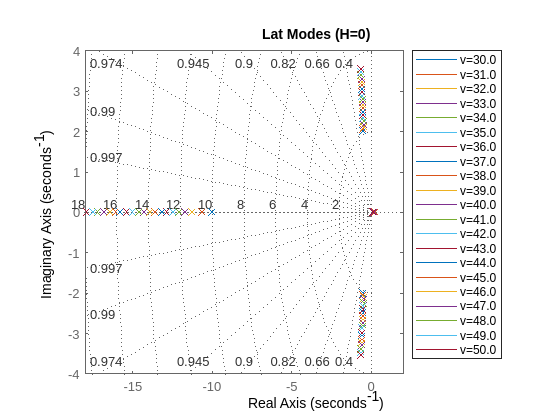

label = sprintf('Lat Modes (H=%.0f)',hRange(idx_h));
title(label);
grid on;
legend('Location','bestoutside');

纵向本体时域仿真

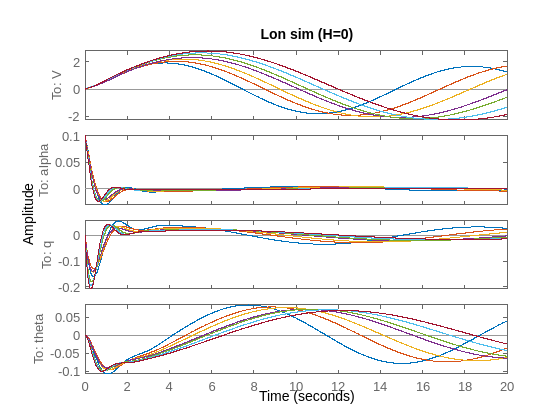

figure;

t=(0:0.01:20)';
u=t*[0 0];
x0=[0;0.1;0;0];
for idx_v=1:3:m
    lsimplot(sysLon{idx_v, idx_h},u,t,x0);
    hold on;
end
label = sprintf('Lon sim (H=%.0f)',hRange(idx_h));
title(label);

横航向本体时域仿真

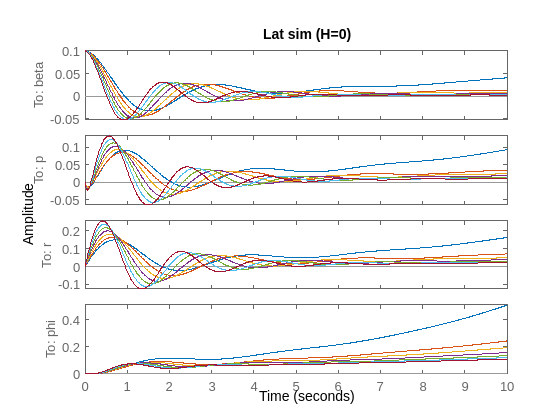


figure;

t=(0:0.01:10)';
u=t*[0 0];
x0=[0.1;0;0;0];
for idx_v=1:3:m
    lsimplot(sysLat{idx_v, idx_h},u,t,x0);
    hold on;
end
label = sprintf('Lat sim (H=%.0f)',hRange(idx_h));
title(label);

纵向本体时域阶跃仿真

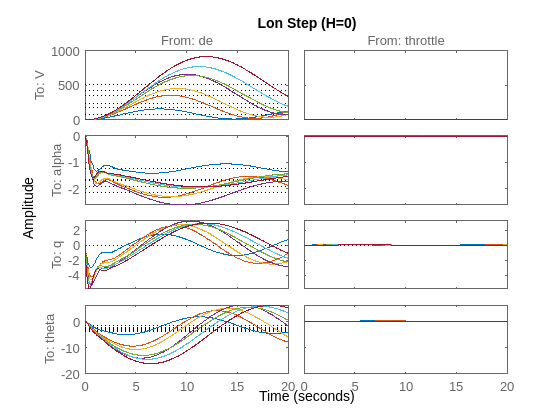

figure;

for idx_v=1:3:m
    stepplot(sysLon{idx_v, idx_h},20);
    hold on;
end
label = sprintf('Lon Step (H=%.0f)',hRange(idx_h));
title(label);

横向本体时域阶跃仿真

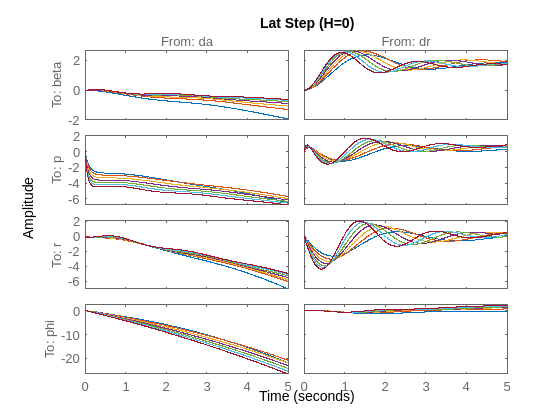

figure;

for idx_v=1:3:m
    stepplot(sysLat{idx_v, idx_h},5);
    hold on;
end
label = sprintf('Lat Step (H=%.0f)',hRange(idx_h));
title(label);